## Flight Control Law Design and Application 

### Term Project Part I ($2^{nd}$ half): Trim & Linearize

**Introduction**

This Matlab livescript is designed for the term project of the course 'Flight Control Law Design and Application'. It comprises all tasks to be done during the second half of Part I of the term project.he script is designed such that it will provide you with information, specific tasks, and checks to verify your solutions. Further, this script will be used by us to verify your results at the end of Part I of the term project. 

**Do's and Don'ts**

In order to use this livescript successfully, you have to fullfill the given **Tasks** (blockwise) in the given order. It is recommended to run the code sections one by one and to valide your results with the implemented checks before advancing. Otherwise, required results for subsequent parts might not be available. Sections can be executed individually with the 'Run Section' Button above.

When running a code section, warnings and error messages might be displayed within this script analog to the usual output in the command window. Use these warnings/errors to correct your solutions if necessary.

All of the tasks in this script refer to the 'AircraftModel_LonMot.slx' model that you completed in the first half of Part I (see the 'FCDA_TermProject_Part_I_1.mlx' livescript). That means, all **Tasks** of the first half of Part I *must be completed before advancing* to the **Tasks** in this script.

In this livescript for the second half of Part I, you will augment the model, find trim points (equilibrium points) of the nonlinear system, linearize the system to obtain linear models of the aircrafts' longitudinal motion, and finally investigate these linear models. 

**Session Start**

This code will run the 'AircraftParameters_LonMot.m' script and load several variables, structs, etc. into your Matlab workspace. Provided this, the 'AircraftModel_LonMot.slx' model is executable. Check the comments within the 'AircraftParameters_LonMot.m' script for further details on the variables, etc.. If not instructed otherwise, do not change the 'AircraftParameters_LonMot.m' script.

**Task 1: **load all required variables, structs, etc. into your Matlab workspace

- to do so, run this section (keyboard short cut: cntr + enter)

clear
clc

addpath('1_Model_LongitudinalMotion')
addpath('1_Model_LongitudinalMotion\1_Checks\')
addpath('2_Model_TrimLinearize')

run("AircraftParameters_LonMot.m"); 

**Trim**

Trimming an aircraft is a very important task that every pilot learns during training. A trim state is an equilibrium point of a the nonlinear 'aircraft' system, i.e. the derivative of the state vector describing the system is $\dot{x}=0$. Hence, the aircraft's states remains unchanged if the system itself does not change (e.g. due to variations in its mass or a shift of its center of gravity) and no external disturbances (such as wind) act on the aircraft. Putting the aircraft in a trim state significantly eases the control and supervision of the aircraft during manual flight, especially over a longer period of time. Considering the longitudinal motion of the aircraft, there exists no single unique trim state. In contrast, the pilot can in principle adjust the aircrafts' state as intended, subject to the relations of state variables and provided that the physical limitations of the system aren't violated.

A trim state of the aircraft is also required if a nonlinear system shall be linearized. The equilibrium state then serves as the reference point for the Taylor series expansion. The therewith obtained linear model is a good approximation of the nonlinear system within a small vicinity around the trim state. Finally, given a linear model, the capabilities of thoroughly developed linear control theory can be applied. Within this project you will use this theory to design linear controllers for your aircraft model. 

**Note:** The 'AircraftModel_LonMot.slx' that you worked with so far is not in a trim state, yet. You can check this for yourself by simply running the simulation for e.g. 100 seconds. You will notice that the aircrafts' states (e.g. $u_f$ and $q$) vary over time, hence $\dot{x} \neq 0$. The initial trim state within your 'AircraftParameters_LonMot.m' script is thus not a real trim state. Fortunately, Matlab comprises a toolbox to compute trim states (equilibrium states) for a nonlinear system in Simulink (see the figure below). With this toolbox, specific presets can be defined for individual system states (or inputs) to be achieved in the trim state.

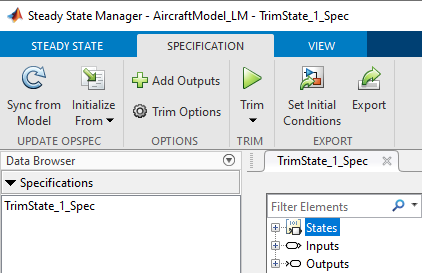

**Task 2:** prepare for trimming the aircraft in three different trim states

- open the 'AircraftModel_LonMot.slx' model and ensure that it is executable by running **Task 1**

- start the 'Steady State Manager' of Matlab (see the 'App' section in your Simulink window)

            

- think for yourself: how many and what states does your model have?

- create three 'Trim Specifications' in the 'Steady State Manager' and rename them to 'TrimState_x_Spec', where $x \in [1,2,3]$ (click on 'Trim Specification')

- run this code section to view the individual trim conditions to attain. What are the differences between them wrt. the objectives and how do the objectives influence the (other) states?

% This code section displays the trim state that you must implement based on the
% information given in the 'MyTrimStates.m' script

run MyTrimStates.m

fprintf(['First Trim State:' '\n' ...
'u   = ' num2str(MyTrimState_1.u) ' ± 0.5 m/s' '\n' ...
'q   = ' num2str(MyTrimState_1.q) ' rad/s' '\n' ...
'Alt = ' num2str(MyTrimState_1.Alt) ' ± 5 m'])

First Trim State:
u   = 130 ± 0.5 m/s
q   = 0 rad/s
Alt = 4000 ± 5 m


fprintf(['Second Trim State:' '\n' ...
'q     = ' num2str(MyTrimState_2.q) ' rad/s' '\n' ...
'Alt   = ' num2str(MyTrimState_2.Alt) ' ± 5 m' '\n' ...
'Theta = ' num2str(MyTrimState_2.Theta) ' rad'])

Second Trim State:
q     = 0 rad/s
Alt   = 4000 ± 5 m
Theta = 0.096 rad

    
fprintf(['Third Trim State:' '\n' ...
'q   = ' num2str(MyTrimState_3.q) ' rad/s' '\n' ...
'Alt = ' num2str(MyTrimState_3.Alt) ' ± 5 m' '\n' ...
'dt  = ' num2str(MyTrimState_3.dt) ' (thrust lever position)'] )

Third Trim State:
q   = 0 rad/s
Alt = 4000 ± 5 m
dt  = 0.7 (thrust lever position)

**Task 3:** trim the aircraft in straight and level flight 

- modify the 'TrimState_1_Spec': include state and/or input specifications to create the first trim state (indicate known (fixed) values by using the check box)

- 'Trim' the aircraft - modify your specification **based on physical insight** in case no solution could be found (hint: help the solver by guessing plausible initial inputs and provide bounds)

- when a solution is found, rename the corresponding 'report' to 'TrimState_1_Report'

- create an 'Operating Point' for the obtained trim state: select the 'TrimState_1_Report' and 'Extract' the 'Operating Point'

- do **not** use the 'Set Initial Condition' button of the 'Steady State Manager'

- rename the operating point to 'TrimState_1_Op'

- export the specification 'TrimState_1_Spec', the report 'TrimState_1_Report', and the operating point 'TrimState_1_Op' to your Matlab workspace

**Task 4:** repeat 'Task 3' for the 2nd and 3rd trim state

- rename the specifications, reports and operating points according the given numbering

- compare your trim reports: how do the individual trim conditions affect the states and inputs?

- save all three specifications, reports and operating points within your workspace into a single 'MyTrimReports.mat'-file (save the file into the '2_Model_TrimLinearize' folder)

**Check:** Run this section to display your trim points.

The trim reports 'TrimState_x_Report' with $x \in [1,2,3]$ will be displayed below. Verify, that the given trim point objectives from 'MyTrimStates.m' are met successfully by checking inputs, outputs, states, and deviation states.

load MyTrimReports.mat

TrimState_1_Report.display

TrimState_1_Report =  Operating point search report for the Model AircraftModel_LonMot.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min          x          Max        dxMin        dx         dxMax   
___________ ___________ ___________ ___________ ___________ ___________
                                                                       
(1.) Alt
   3995      3999.9992     4005          0       1.565e-12       0     
(2.) Theta
    -90      0.072196       90           0           0           0     
(3.) q
     0           0           0  

TrimState_2_Report.display

TrimState_2_Report =  Operating point search report for the Model AircraftModel_LonMot.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min          x          Max        dxMin        dx         dxMax   
___________ ___________ ___________ ___________ ___________ ___________
                                                                       
(1.) Alt
   3995      4000.0289     4005          0      1.7231e-12       0     
(2.) Theta
   0.096       0.096       0.096         0           0           0     
(3.) q
     0           0           0  

TrimState_3_Report.display

TrimState_3_Report =  Operating point search report for the Model AircraftModel_LonMot.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min          x          Max        dxMin        dx         dxMax   
___________ ___________ ___________ ___________ ___________ ___________
                                                                       
(1.) Alt
   3995        4005        4005          0      -1.1484e-09      0     
(2.) Theta
   -Inf      0.0084418      Inf          0           0           0     
(3.) q
     0           0           0  

**Linearization**

In order to apply linear control theory, you need to obtain a linear model of the nonlinear system. This linear model is a good approximation of the 'true system' in the vicinity of a trim state. Within the lecture, the differential equations describing the aircrafts' motion were linearized analytically. A linearization by hand is not only error prone, but might not even be feasible for very complex systems. Moreover, a linearization by hand will most likely include several additional approximations to ease computation. Fortunately, again, Matlab provides a toolbox to linearize nonlinear systems numerically.

**Task 5:** linearize the nonlinear aircraft model

- open the 'AircraftModel_LonMot.slx' model and ensure that it is executable by running **Task 1**

- load the 'TrimState_1_Op' operating point (trim point) from the 'MyTrimReports' mat.-file into your Matlab workspace

- open the 'Model Linearizer' app of Matlab (see the 'Apps' section in your Simulink window)

          

- specify the inputs and outputs your linear model shall have within the 'Linear Analysis' section in the 'Model Linearizer': select 'Analysis I/Os' as 'Root Level Inports and Outports' (see figure below) 

- specify the expansion point for the Taylor series expansion, i.e., the trim point: select 'TrimState_1_Op' as the 'Operating Point' in the 'Linear Analysis' section (see figure below) 

- within 'More Options' enable state ordering and define the following state order:  u, w, q, Theta, Alt 

- linearize the model by selecting 'Linearize' in the drop down menu shown below (see second figure)

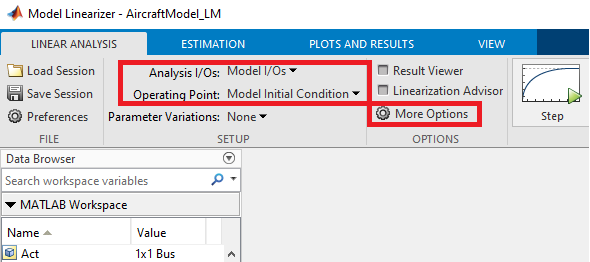

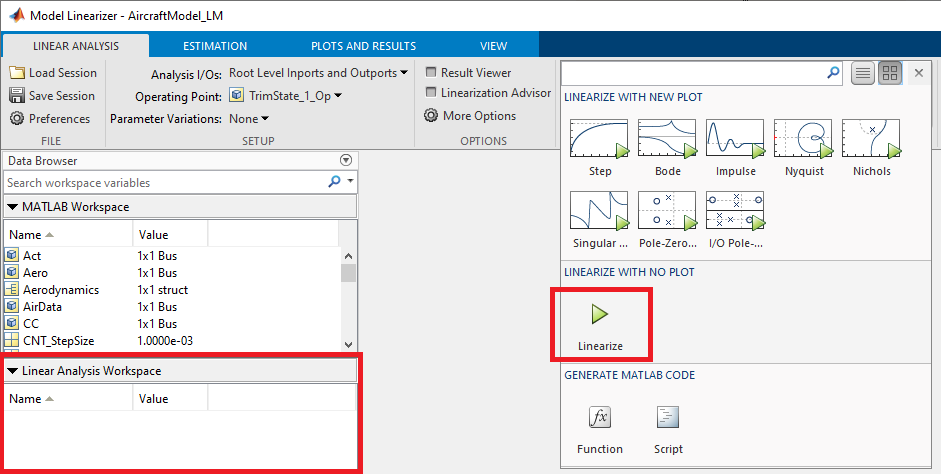LinearLonModel

- rename the newly created linear model 'linsys1' in the 'Linear Analysis Workspace' to 'LinearLonModel_Initial'

- export the linear model to your Matlab workspace (e.g. use drag & drop within the 'Model Linearizer' or right-click the model depending on your MATLAB version)

- use the subsequent **'Check'** code section to check the state names, input names and output names of the linear model

- In case some (output) names include an additional path (e.g. 'AircraftModel_LonMot/q'), shorten it to the variable name only: type **LinearLonModel_Initial.OutputName{1} = 'q';**  into your Matlab command window and repeat for the other outputs

- add units to *every input and output*: type e.g. **LinearLonModel_Initial.OutputUnit{1} = 'm/s';** into your Matlab command window (use '-' for normalized signals). Also repeat for the other outputs

- save the linear model into a new .mat-file named 'TrimState_1_LinearLonModel_Initial.mat' (save it into the '2_Model_TrimLinearize' folder)

**Check:**  check the state names, input names and output names of the linear model 'LinearLonModel_Initial'.

load TrimState_1_LinearLonModel_Initial.mat
LinearLonModel_Initial.StateName

ans = 5×1 cell array
    {'u'    }
    {'w'    }
    {'q'    }
    {'Theta'}
    {'Alt'  }


LinearLonModel_Initial.InputName

ans = 2×1 cell array
    {'cmd_de'}
    {'cmd_dt'}


LinearLonModel_Initial.InputUnit

ans = 2×1 cell array
    {'-'}
    {'-'}


LinearLonModel_Initial.OutputName

ans = 8×1 cell array
    {'q'    }
    {'u'    }
    {'w'    }
    {'Theta'}
    {'gamma'}
    {'Alt'  }
    {'n_z'  }
    {'alpha'}


LinearLonModel_Initial.OutputUnit

ans = 8×1 cell array
    {'rad/s'}
    {'m/s'  }
    {'m/s'  }
    {'rad'  }
    {'rad'  }
    {'m'    }
    {'-'    }
    {'rad'  }


clear ans

**Check:** check whether the step resonses of the linear model are reasonable. Note that the engines on the 'VFW 614' aircraft are located above the wings, i.e. in negative $z_f$ - direction wrt. the center of gravity. Further note, that a negative step is applied to the elevator.

% get step responses
[qde,time] = step(LinearLonModel_Initial('q','cmd_de')*-0.05,6); [ude] = step(LinearLonModel_Initial('u','cmd_de')*-0.05,6); [alphade] = step(LinearLonModel_Initial('alpha','cmd_de')*-0.05,6); 
% note that the step height for the commanded elevator deflection (cmd_de) is reduced to 0.05 rad (instead of 1 rad) to have a realistic deviation from the trim deflection 
[qdt] = step(LinearLonModel_Initial('q','cmd_dt')*0.2,6);  [udt] = step(LinearLonModel_Initial('u','cmd_dt')*0.2,6); [alphadt] = step(LinearLonModel_Initial('alpha','cmd_dt')*0.2,6); 
% note that the step height for the thrust lever position (cmd_dt) is reduced to 20 % (instead of 100 %) to have a realistic deviation from the trim setting

% create figure
figure(200); clf
    subplot(3,2,1), plot(time,qde,'LineWidth',2), grid on, title('Input: $\Delta \delta_e$',"Interpreter","latex","FontSize",14), xlabel(''), ylabel('Output: $\tilde{q}$', "Interpreter","latex","FontSize",13)  
    subplot(3,2,2), plot(time,qdt,'LineWidth',2), grid on, title('Input: $\Delta \delta_t$',"Interpreter","latex","FontSize",14), ylabel('')   
    subplot(3,2,3), plot(time,ude,'LineWidth',2), grid on, title(''), ylabel('Output: $\tilde{u}$', "Interpreter","latex","FontSize",13)
    subplot(3,2,4), plot(time,udt,'LineWidth',2), grid on, title(''), ylabel('')
    subplot(3,2,5), plot(time,alphade,'LineWidth',2), grid on, title(''), xlabel('Time (s)'), ylabel('Output: $\tilde{\alpha}$', "Interpreter","latex","FontSize",13)
    subplot(3,2,6), plot(time,alphadt,'LineWidth',2), grid on, title(''), xlabel('Time (s)'), ylabel('')
    annotation('textbox', [0.35 0.99 0.1 0.02],'String','(Scaled) Step Inputs','LineStyle','none','Interpreter','latex','FontSize',13,'FitBoxToText','on');
clear time qde qdt ude udt alphade alphadt

**State Space Transformation**

Recall that there is no unique coordinate system for describing the state space of a dynamic system. The linear model you obtained has states that are physically meaningful. This significantly eases interpretation. Still we intend to change the state space, more specifically, we want to exchange the normal velocity $w$ with the angle of attack $\alpha$ analog to the lecture. Recall from the lecture, that for small angles the angle of attack can be approximated with $\alpha \approx w/\sqrt{(u^2+w^2)}$. 

**Task 6:** perform a state space transformation for the linear model  'LinearLonModel'

- uncomment the complete code section below (select every line and use the shortcut 'cntr + T') 

- augment the code within the highlighted part:  

- load the linear aircraft model 'LinearLonModel_Initial' into your Matlab workspace

- define a scalar variable 'Va_bar' and calculate the trim airspeed $\bar{V}_a = \sqrt{(\bar{u}^2+\bar{w}^2)}$:  get the trim values of $\bar{u}$ and $\bar{w}$ from the 'TrimState_1_Report' (load the report and type  **'TrimState_1_Report'** into your Matlab command window) 

load TrimState_1_LinearLonModel_Initial.mat
% --------------------start of your code -------------------------- %

load MyTrimReports.mat

  u_bar = TrimState_1_Report.states(4).x

u_bar = 130.1729

  w_bar = TrimState_1_Report.states(5).x

w_bar = 9.4143


  Va_bar = sqrt(u_bar^2+w_bar^2)

Va_bar = 130.5129


% --------------------end of your code ---------------------------- %


- perform the state space transformation with the subsequent line of code; type 'help ss2ss' and 'help blkdiag' into the command window or go to [Link:ss2ss](https://www.mathworks.com/help/control/ref/ss.ss2ss.html) and [Link:blkdiag](https://www.mathworks.com/help/matlab/ref/blkdiag.html) to get additional insight into the function we use in this operation

LinearLonModel = ss2ss(LinearLonModel_Initial,blkdiag(1,1/Va_bar,1,1,1));  % transforms the state space of the linear aricraft model. Note that only the second state is affected by the transformation, i.e. w --> w/Va = alpha

- the state transformation erases the state names (make sure of it yourself by typing **LinearLonModel.StateName **into your Matlab command window). Note that the input and output names and units remain unchanged (this is correct as the transformation only affects the states).

- redefine the state names in the correct order ('u', **'alpha'**, 'q', 'Theta', 'Alt') by typing **LinearLonModel.StateName{1} = 'u';**  etc. into your Matlab command window

- define the state units for 'u', 'alpha', 'q', 'Theta', 'Alt'  by typing **LinearLonModel.StateUnit{1} = 'm/s';**  etc. into your Matlab command window

- save the transformed linear model to a new .mat file named 'TrimState_1_LinearLonModel.mat' (save it into the '2_Model_TrimLinearize' folder)

**Check: **check the state names, input names and output names of the linear model 'LinearLonModel'

load TrimState_1_LinearLonModel.mat

LinearLonModel.StateName

ans = 5×1 cell array
    {'u'    }
    {'alpha'}
    {'q'    }
    {'Theta'}
    {'Alt'  }


LinearLonModel.StateUnit

ans = 5×1 cell array
    {'m/s'  }
    {'rad'  }
    {'rad/s'}
    {'rad'  }
    {'m'    }


LinearLonModel.InputName

ans = 2×1 cell array
    {'cmd_de'}
    {'cmd_dt'}


LinearLonModel.InputUnit

ans = 2×1 cell array
    {'-'}
    {'-'}


LinearLonModel.OutputName

ans = 8×1 cell array
    {'q'    }
    {'u'    }
    {'w'    }
    {'Theta'}
    {'gamma'}
    {'Alt'  }
    {'n_z'  }
    {'alpha'}


LinearLonModel.OutputUnit

ans = 8×1 cell array
    {'rad/s'}
    {'m/s'  }
    {'m/s'  }
    {'rad'  }
    {'rad'  }
    {'m'    }
    {'-'    }
    {'rad'  }


clear ans

Moreover, we want to create a second linear model named 'LinearLonModel_Phasor' for later use. For the  'LinearLonModel_Phasor' model we intend to temporarily change the units of the angles $\alpha$ and $\Theta$ from 'rad' to 'deg' as well as the unit of the pitch rate $q$ from 'rad/s' to 'deg/s'. We do this scaling in order to get a phasor plots in Task 10, that is easier to interpret.

**Task 7:** create a second transformed linear model for later use

- load the (already transformed) linear aircraft model 'LinearLonModel' of Task 6 into your Matlab workspace

- perform a state space transformation with the subsequent code line

load TrimState_1_LinearLonModel.mat

LinearLonModel_Phasor = ss2ss(LinearLonModel,blkdiag(1,180/pi,180/pi,180/pi,1));  % transforms the state space of the linear aricraft model. Note that 'alpha', 'q', and 'Theta' are affected only

- redefine the state names of the new model by typing **LinearLonModel_Phasor.StateName = LinearLonModel.StateName;** into your Matlab command window

- define the state units for 'u', 'alpha', 'q', 'Theta', 'Alt'  by typing **LinearLonModel_Phasor.StateUnit{1} = 'm/s';**  etc. into your Matlab command window (this should also make clear why this step is important!)

- save the 'LinearLonModel_Phasor' model into a new .mat file named 'TrimState_1_LinearLonModel_Phasor.mat' (save it into the '2_Model_TrimLinearize' folder)

**Check: **check the state names, input names and output names of the linear model 'LinearLonModel_Phasor'

load TrimState_1_LinearLonModel_Phasor.mat

LinearLonModel_Phasor.StateName

ans = 5×1 cell array
    {'u'    }
    {'alpha'}
    {'q'    }
    {'Theta'}
    {'Alt'  }


LinearLonModel_Phasor.StateUnit

ans = 5×1 cell array
    {'m/s'  }
    {'deg'  }
    {'deg/s'}
    {'deg'  }
    {'m'    }


LinearLonModel_Phasor.InputName

ans = 2×1 cell array
    {'cmd_de'}
    {'cmd_dt'}


LinearLonModel_Phasor.InputUnit

ans = 2×1 cell array
    {'-'}
    {'-'}


LinearLonModel_Phasor.OutputName

ans = 8×1 cell array
    {'q'    }
    {'u'    }
    {'w'    }
    {'Theta'}
    {'gamma'}
    {'Alt'  }
    {'n_z'  }
    {'alpha'}


LinearLonModel_Phasor.OutputUnit

ans = 8×1 cell array
    {'deg/s'}
    {'m/s'  }
    {'m/s'  }
    {'deg'  }
    {'deg'  }
    {'m'    }
    {'-'    }
    {'deg'  }


**Eigenvalues & Eigenvectors**

Recall from the lecture and the notes that both, the eigenvectors $\nu$ and eigenvalues $\lambda$ are required to be able to interpret the behavior of a dynamic system. Consider the free response of the aircraft: For any initial condition $x_0$, the time response of the aircraft is determined not only by the eigenvalues, but also by the corresponding eigenvectors of the system matrix. The eigenvalues $\lambda_i = \sigma_i \pm j\omega_i$ define the frequency of oscillations in the response. Further, the real part of the eigenvalues implies whether these oscillations grow or decay. In fact, a system is stable if and only if the real part of all eigenvalues are negative, i.e. $Re(\lambda) <0$. On the other hand, the amplitude and phase shift of the individual state variable's oscillations depend on the eigenvectors of the system.

Among others, Matlab provides two useful functions to investigate the dynamics of a system. The `damp `function computes the eigenvalues of the system as well as the corresponding damping ratios $\zeta_i = -\sigma_i/\omega_{n,i}$ and natural frequencies $\omega_{n,i} = |\lambda_i|$. The `eig` function of Matlab computes the eigenvalues and (left and right) eigenvectors of a system. Note that the state space transformation of Tasks 6 & 7 do not change the eigenvalues of the system. (They do change the eigenvectors.)

**Task 8:** compute important quantities to investigate the dynamic properties of the aircraft 

- use the 'LinearLonModel_Phasor' model of Task 7: make sure it is in your Matlab workspace

- uncomment the complete code section below (select every line and use the shortcut 'cntr + T') 

- compute the modal matrix $M$ consisting of the (right) eigenvectors and the diagonal matrix $D$ containing the eigenvalues $\lambda_i$ of the linear model (we called this matrix $\Lambda$ in the lecture)

- define a column vector 'lamda' comprising the eigenvalues (use code, don't type in the vector by hand)

- compute the natural frequencies and damping ratios: use $\omega_{n,i} = |\lambda_i|$ and $\zeta_i = -\sigma_i/\omega_{n,i}$ and store the results in column vectors named 'omega_n' and 'zeta'

- compare your results to the output of Matlabs' `damp` command

- **save the changes you've made within this livescript**

- check for yourself that the state space transformation of Task 7 did not change the eigenvalues of the system: compare the outputs of `damp(LinearLonModel)` and `damp(LinearLonModel_Phasor)`

 load TrimState_1_LinearLonModel_Phasor.mat
 
% % --------------------start of your code -------------------------- %

 [M,D,~] = eig(LinearLonModel_Phasor.A);
 
 lambda = diag(D) % vector of eigenvalues

lambda =   -0.6643 + 2.3234i
  -0.6643 - 2.3234i
  -0.0056 + 0.1127i
  -0.0056 - 0.1127i
  -0.0005 + 0.0000i


 
 omega_n = abs(lambda) % vectors of natural frequencies

omega_n =     2.4165
    2.4165
    0.1128
    0.1128
    0.0005


     
 zeta = -real(lambda)./omega_n % vector of damping factors

zeta =     0.2749
    0.2749
    0.0495
    0.0495
    1.0000


     
% % --------------------end of your code -------------------------- %
 
 T = table(lambda , zeta , omega_n, 'VariableNames', {'  Eigenvalue  ';'Damping Ratio';'Natural Frequency'})   % display all eigenvalues, damping factors and natural frequencies

T = 5×3 table
         Eigenvalue         Damping Ratio    Natural Frequency
    ____________________    _____________    _________________

       -0.66435+2.3234i        0.27492              2.4165    
       -0.66435-2.3234i        0.27492              2.4165    
      -0.005587+0.11266i      0.049533              0.1128    
      -0.005587-0.11266i      0.049533              0.1128    
    -0.00045912+0i                   1          0.00045912    


 
 damp(LinearLonModel_Phasor)        % compute eigenvalues (poles), damping ratio and natural frequencies

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.59e-04                 1.00e+00       4.59e-04         2.18e+03    
 -5.59e-03 + 1.13e-01i     4.95e-02       1.13e-01         1.79e+02    
 -5.59e-03 - 1.13e-01i     4.95e-02       1.13e-01         1.79e+02    
 -6.64e-01 + 2.32e+00i     2.75e-01       2.42e+00         1.51e+00    
 -6.64e-01 - 2.32e+00i     2.75e-01       2.42e+00         1.51e+00    


 
 load TrimState_1_LinearLonModel.mat
 
 damp(LinearLonModel)        % compute eigenvalues (poles), damping ratio and natural frequencies

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.59e-04                 1.00e+00       4.59e-04         2.18e+03    
 -5.59e-03 + 1.13e-01i     4.95e-02       1.13e-01         1.79e+02    
 -5.59e-03 - 1.13e-01i     4.95e-02       1.13e-01         1.79e+02    
 -6.64e-01 + 2.32e+00i     2.75e-01       2.42e+00         1.51e+00    
 -6.64e-01 - 2.32e+00i     2.75e-01       2.42e+00         1.51e+00    


**Dynamic Modes**

Recall from the lecture that the longitudinal flight dynamics comprises two dynamic modes: the 'fast' short period mode and the 'slow' phugoid mode. The term 'fast' refers to the relatively high frequency of the dynamic mode, which corresponds to short periods of time during which the longitudinal motion of the aircraft is dominated by this mode. In contrast, the 'slow' phugoid mode dominates the longitudinal motion of the aircraft long after the short period mode decayed. Each dynamic mode corresponds to one complex conjugate pair of eigenvalues (poles).

**Task 9:** link the dynamic modes to the corresponding eigenvalues

- load the linear model 'LinearLonModel**_Phasor**' into your workspace

- uncomment the complete code section below (select every line and use the shortcut 'cntr + T') 

- augment the code within the highlighted part:  

- link the short period mode to the 'fast' complex conjugate pair of eigenvalues of the linear model (highest natural frequency $\omega_n$)

- link the phugoid mode to the 'slow' complex conjugate pair of eigenvalues of the linear model (lowest natural frequency $\omega_n$)

- link the remaining fifth eigenvalue to the 'altitude mode'

- plot the poles into the complex plane using the provided function `polemap `(ensure that the 'polemap.m' is in the active path; this function is not part of Matlab and written for this class. Matlab has the function `pzmap` to generate a similar plot.)

- **save the changes you've made within this livescript**

To get a better understanding of the matter: compare your pole map for the 'VFW 614' aircraft to the pole map of the 'Airbus A330 like' aircraft used in the lecture notes --> Is your result reasonable? Compare the damping ratios and the natural frequencies of the short period modes: is the dynamic mode of the 'Airbus A330 like' aircraft 'faster' or 'slower'? What can be said about the short period damping? Also think about the additional 'altitude pole', located almost at the origin of the complex plane. What does it represent? Is this plausible?

 load TrimState_1_LinearLonModel_Phasor.mat
 
% % --------------------start of your code -------------------------- %
 
 idx_sp  = [1 2];  % e.g. idx_sp = [1 4] --> indices of the eigenvalues within the vector of eigenvalues 'lambda' corresponding to the short period mode (sp) 
 idx_ph  = [3 4];  % indices of the eigenvalues within the vector of eigenvalues 'lambda' corresponding to the phugoid mode (ph)  
 idx_alt = [5];      % index of the eigenvalue within the vector of eigenvalues 'lambda' corresponding to the 'altitude mode'
 
% % --------------------end of your code -------------------------- %
 
 figure(210); clf
 polemap(LinearLonModel_Phasor,idx_sp,idx_ph,idx_alt)

**Check: **display the computed eigenvalues assigned to the dynamic modes of the aircraft.

Note, for this check Task 8 has to be executed.

fprintf(['Short Period Mode:' '       Phugoid Mode:' '       Altitude Mode:' '\n' ...
        num2str(lambda(idx_sp(1))) '       ' num2str(lambda(idx_ph(1))) '       ' num2str(lambda(idx_alt)) '\n' ...
        num2str(lambda(idx_sp(2))) '       ' num2str(lambda(idx_ph(2))) '       '])

Short Period Mode:       Phugoid Mode:       Altitude Mode:
-0.66435+2.3234i       -0.005587+0.11266i       -0.00045912
-0.66435-2.3234i       -0.005587-0.11266i       

**Phasor Diagrams and Mode Responses**

**Task 10:** investigate the modal respones by creating phasor diagrams and modal responses

- load the transformed linear model 'LinearLonModel**_Phasor**' into your workspace

- uncomment the code section below

- augment the code to plot the phasor diagrams for the short period mode, the phugoid mode and the 'altitude mode' using the provided `phasor` function - take a look into the function to explore its mechanisms! (you can type 'open phasor.m' into the command window to do this)

- plot the modal responses of the short period mode, the phugoid mode and the 'altitude mode' using the (provided) `mode_resp` function - take a look into the function to explore its mechanisms!

- **save the changes you've made within this livescript**

Compare your results for the 'VFW 614' aircraft with the plots of the 'Airbus A330 like' aircraft in the lecture notes. Does the 'VFW 614' show similar phasor diagrams and mode responses as the 'Airbus A330 like' aircraft? Think about why we decided to express the angles in degrees rather than in radians for this analysis. What does the scale of the altitude phasor and its location wrt. the other signals tell you about the contribution of the 'Alt' state to the dynamic modes under investigation? What do the plots tell you about the 'altitude mode'? Does the time response of the 'altitude mode' meet your expectations (recall the damping ratio and the natural eigenfrequency of that mode)? Is the altitude a 'fast' or 'slow' state?

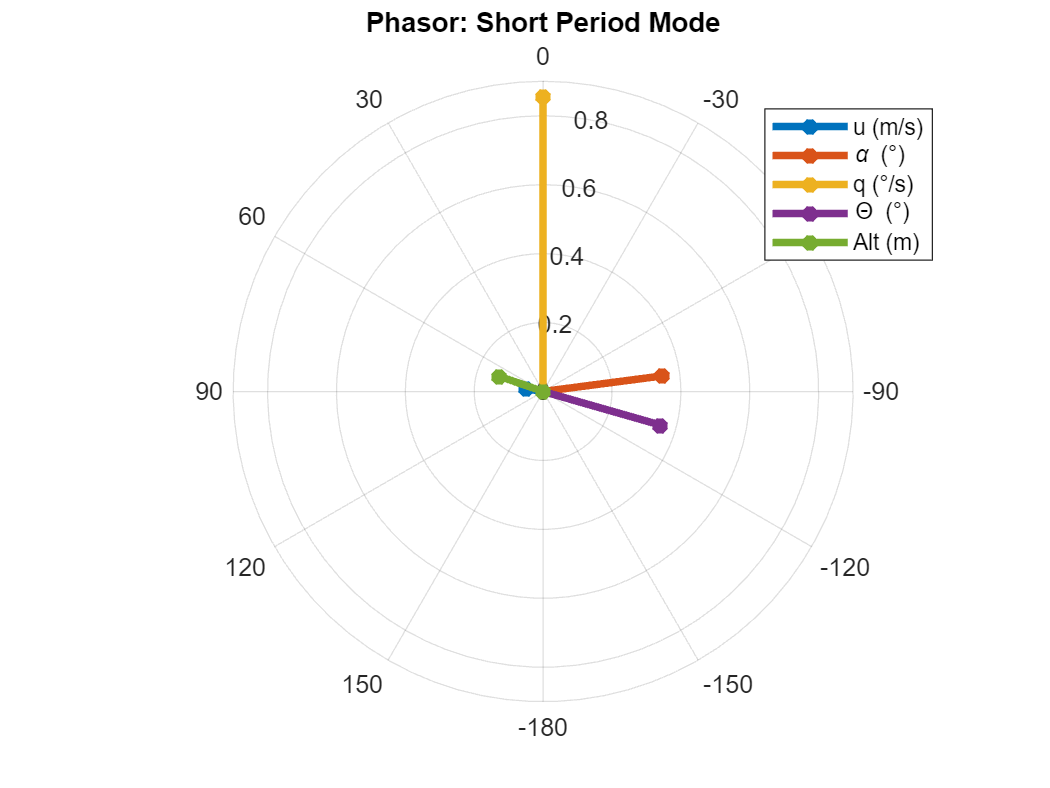

 load TrimState_1_LinearLonModel_Phasor.mat
 
 % --------------------start of your code -------------------------- %
 
 figure(220); clf
 phasor(LinearLonModel_Phasor, [1 2]), title('Phasor: Short Period Mode')

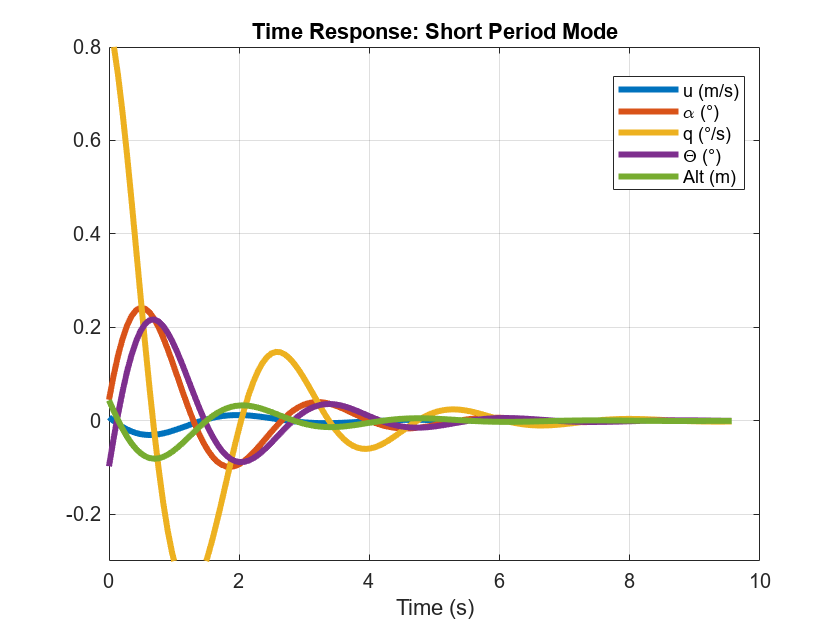

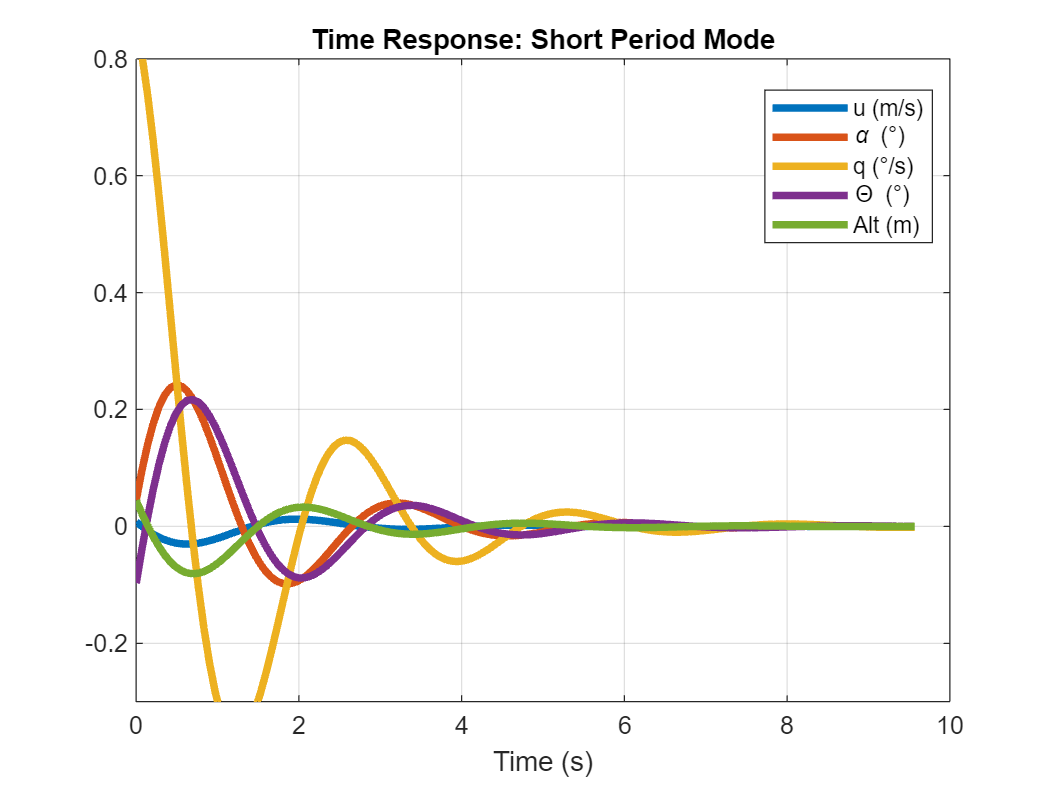

 figure(221); clf
 mode_resp(LinearLonModel_Phasor, [1 2], [-0.3 0.8]), title('Time Response: Short Period Mode')

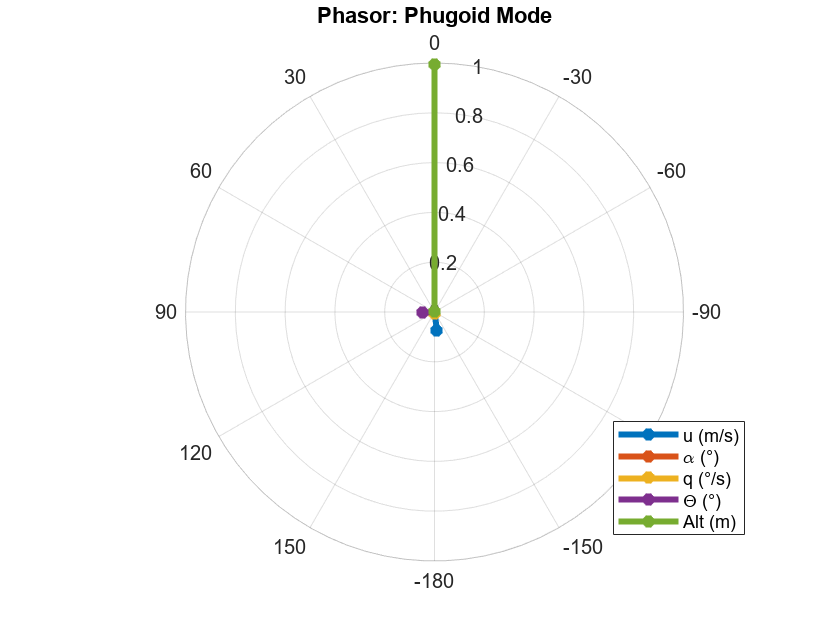

 figure(222); clf
 phasor(LinearLonModel_Phasor, [3 4]), title('Phasor: Phugoid Mode')

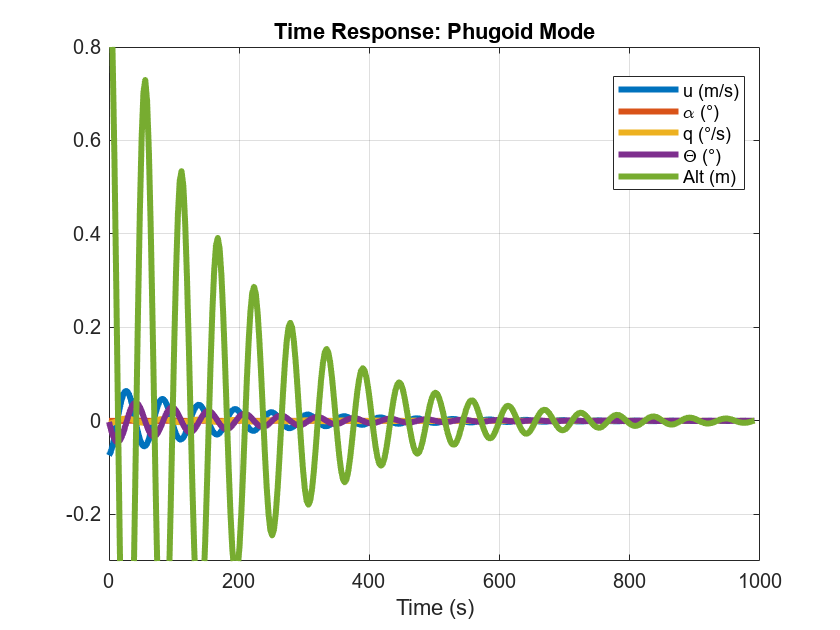

 figure(223); clf
 mode_resp(LinearLonModel_Phasor, [3 4],[-0.3 0.8]), title('Time Response: Phugoid Mode')

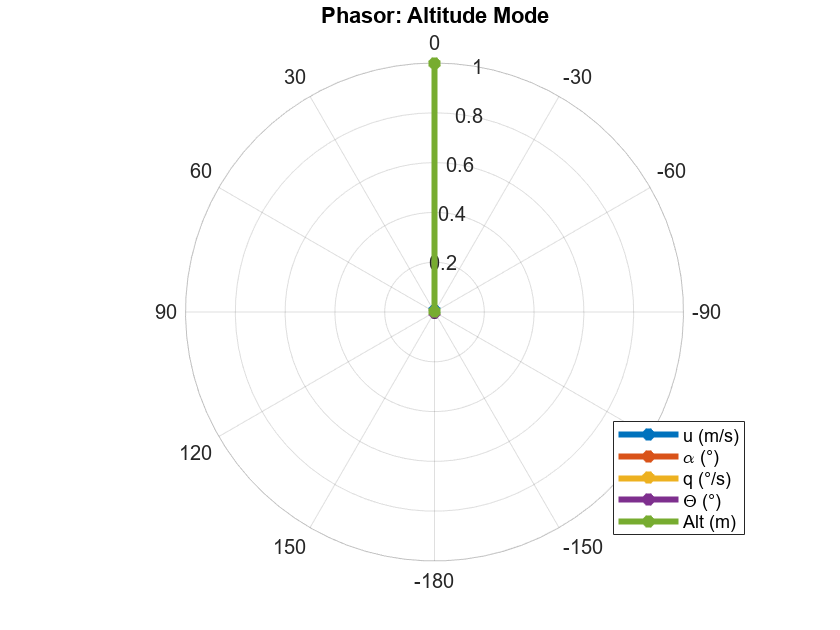

 figure(224); clf
 phasor(LinearLonModel_Phasor, [5]), title('Phasor: Altitude Mode'),

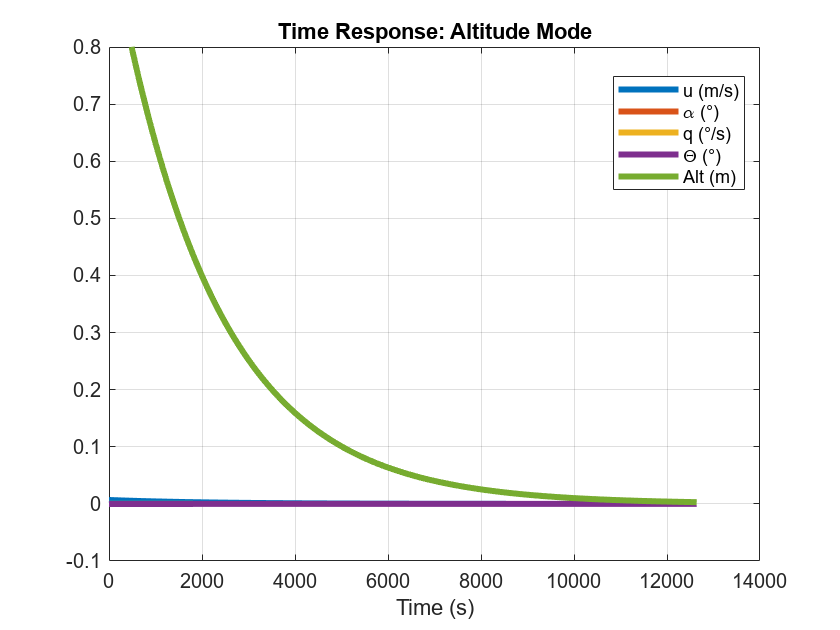

 figure(225); clf
 mode_resp(LinearLonModel_Phasor, [5], [-0.1 0.8]), title('Time Response: Altitude Mode')

% % --------------------end of your code -------------------------- %

**Modal Decomposition**

The lecture discussed that the aircraft model can be decomposed into a sum of dynamic modes and further that these modes can be represented in a real-valued state space form. Matlabs `canon `command implements the state space transformation that represents a model in its real-valued modal form and also returns the transformation matrix for this operation.

Modes that contribute little to the system response can be neglected to simplify the model, which is useful for control design. Recall that the system response over a short time horizon is very well approximated by the short period mode, alone. You will now extract the second-order short period model from the linearized aircraft model. This model will be used later for control design, e.g. for the direct pole placement method. Matlab's  `modred `function can be used to remove states from a state space model. Its syntax is `modred(sys,elim,method`), where `sys` is the system from which states are removed, `elim` is a vector with indices of the states that are removed (e.g. [1 2] for removing the first two states of `sys`) and `method` is either `'truncate'` or `'residualize' `(note that the data type of the `method` input is *string*) to specify whether truncation or residualization is used to remove the states.

**Task 11:** Obtain the second-order short period model

- run the following code section to calculate the real-valued modal form

load TrimState_1_LinearLonModel.mat

[ModalForm, Tmod] = canon(LinearLonModel); % obtain the real-valued modal form of the model
ModalForm.StateName = []; % erase the state names; canon unfortunately forgets to do this 
ModalForm.StateUnit = []; % erase the state units; canon unfortunately forgets to do this
ModalForm.a               % state matrix of modal form; note that this is Tmod*LinearLonModel.a*inv(Tmod)

ans =    -0.6643    2.3234         0         0         0
   -2.3234   -0.6643         0         0         0
         0         0   -0.0056    0.1127         0
         0         0   -0.1127   -0.0056         0
         0         0         0         0   -0.0005


- uncomment the subsequent code section

- inspect the system matrix of the 'ModalForm' and define indices to identify the dynamic modes (recall the special form of the system matrix with real parts and imaginary parts of the eigenvalues appearing directly as entries)

- use Matlab's `modred` command to remove the phugoid mode and the altitude mode from the modal form model 'ModalForm'; decide whether you need to apply truncation or residualization

% --------------------start of your code -------------------------- %
 
 idx_sp  = [1 2];  % e.g. idx_sp = [1 2] --> eigenvalues of short period mode are located in the block ModalForm.a([1 2],[1 2])
 idx_ph  = [3 4];  % e.g. idx_ph = [3 4] --> eigenvalues of phugoid mode are located in the block ModalForm.a([3 4],[3 4])
 idx_alt = [5];  % e.g. idx_alt = 5 --> eigenvalue of altitude mode is located in the entry ModalForm.a(5,5)
 
 sys.Scaled = true;
 SPModalForm = modred(ModalForm, [idx_ph idx_alt],'truncate');
 % --------------------end of your code -------------------------- %

- plot the responses of the linearized model 'LinearLonMot' and the short period model 'SPModalForm' to a -5° step in the elevator deflection using the subsequent code section

- look at the step response that compares the step responsens (-5° elevator deflection) of the linearized model and the short period model. Are there visible differences in the responses? If so, do they meet your expectations? 

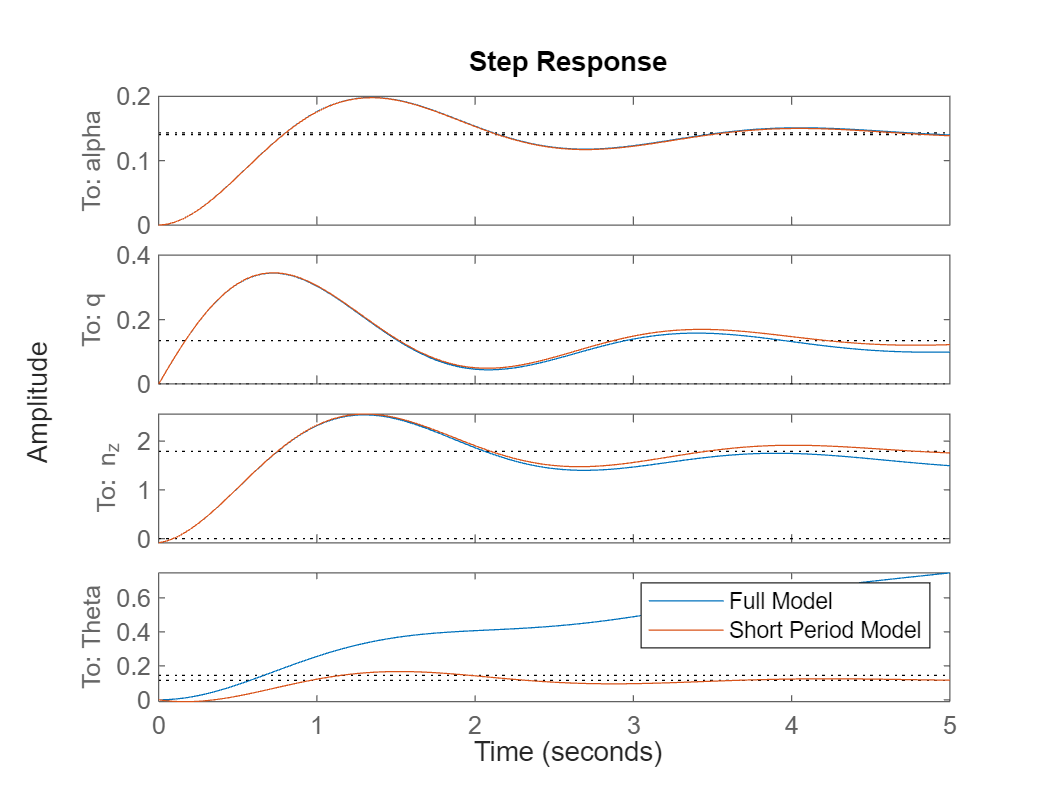

figure(230); clf
step(LinearLonModel({'alpha','q','n_z','Theta'},'cmd_de')*deg2rad(-5),...
     SPModalForm({'alpha','q','n_z','Theta'},'cmd_de')*deg2rad(-5),5)
legend('Full Model','Short Period Model')

For now, the short period model 'SPModalForm' is in modal coordinates (that we can relate to the physical meaningful state variables through the eigenvector). You will use the short period model later for control design. Specifically, you will use the pole placement method that requires the state variables to be measurable for feedback. For this, it is useful to express the model also in state variables that are physically meaningful. The `canon `function did not only return the (real-valued) modal form, but also the (real-valued) transformation matrix $\xi = T_\text{mod}\,x$ that relates the modal coordinates $\xi$ and the original state vector $x$ (this transformation is the matrix of real and imaginary parts of the eigenvectors as discussed in the lecture). We can use this matrix to find the relation between $\alpha$, $q$ and the short period modal states $\xi_{SP}$. Specifically, we want to construct the transformation matrix $T_{SP, \alpha q}$ such that $\xi_{SP} = T_{SP, \alpha q}\, [ \alpha \quad q ]^T$. Note that this transformation matrix is a sub block of the transformation $T_\text{mod}$ and consists of the **colums** that belong to $\xi_{SP}$ and the **rows** that belong to $\alpha$ and $q$. Consequently, we can transform the short period model states from modal coordinates in 'SPModalForm' into physically meaningful coordinates using $[\alpha \quad q]^T = T_{SP, \alpha q}^{-1}\,\xi_{SP}$. This is implemented in the following code section, where you only need to specify the correct indices for $\alpha$ and $q$.

- uncomment the subsequent code section

- transform the short period model 'SPModelForm' to a state space representation that uses 'alpha' and 'q' as state variables; do this by setting the required indices to construct the necessary transformation matrix in the prepared code section

% --------------------start of your code -------------------------- %
 
 idx_alpha = [2]; % index of 'alpha' in state vector of the LinearLonModel
 idx_q = [3];     % index of 'q' in state vector of the LinearLonModel
 
% --------------------end of your code -------------------------- %
 
 T_SP_alphaq = Tmod(idx_sp, [idx_alpha idx_q]) ; % transformation matrix realting modal coordinates to the original state vector
 
 SPModel = ss2ss( SPModalForm, inv(T_SP_alphaq) ) % get short period model in original state vector coordinates

SPModel =
 
  A = 
            x1       x2
   x1  -0.9734   0.9631
   x2   -5.704  -0.3553
 
  B = 
          cmd_de     cmd_dt
   x1   -0.07428  -0.002626
   x2     -9.752    -0.0974
 
  C = 
                  x1          x2
   q        -0.00708       1.001
   u          -7.766      0.9218
   w           130.2     0.02203
   Theta      0.9779     -0.1656
   gamma    -0.02145     -0.1653
   Alt         -20.9       4.058
   n_z         12.84      0.4959
   alpha      0.9994  -0.0003411
 
  D = 
           cmd_de   cmd_dt
   q            0        0
   u            0        0
   w            0        0
   Theta        0        0
   gamma        0        0
   Alt          0        0
   n_z     0.9883  0.01457
   alpha        0        0
 
Continuous-time state-space model.


 SPModel.StateName = LinearLonModel.StateName([idx_alpha, idx_q]) % define state names

SPModel =
 
  A = 
            alpha        q
   alpha  -0.9734   0.9631
   q       -5.704  -0.3553
 
  B = 
             cmd_de     cmd_dt
   alpha   -0.07428  -0.002626
   q         -9.752    -0.0974
 
  C = 
               alpha           q
   q        -0.00708       1.001
   u          -7.766      0.9218
   w           130.2     0.02203
   Theta      0.9779     -0.1656
   gamma    -0.02145     -0.1653
   Alt         -20.9       4.058
   n_z         12.84      0.4959
   alpha      0.9994  -0.0003411
 
  D = 
           cmd_de   cmd_dt
   q            0        0
   u            0        0
   w            0        0
   Theta        0        0
   gamma        0        0
   Alt          0        0
   n_z     0.9883  0.01457
   alpha        0        0
 
Continuous-time state-space model.


 SPModel.StateUnit = LinearLonModel.StateUnit([idx_alpha, idx_q]) % define state units

SPModel =
 
  A = 
            alpha        q
   alpha  -0.9734   0.9631
   q       -5.704  -0.3553
 
  B = 
             cmd_de     cmd_dt
   alpha   -0.07428  -0.002626
   q         -9.752    -0.0974
 
  C = 
               alpha           q
   q        -0.00708       1.001
   u          -7.766      0.9218
   w           130.2     0.02203
   Theta      0.9779     -0.1656
   gamma    -0.02145     -0.1653
   Alt         -20.9       4.058
   n_z         12.84      0.4959
   alpha      0.9994  -0.0003411
 
  D = 
           cmd_de   cmd_dt
   q            0        0
   u            0        0
   w            0        0
   Theta        0        0
   gamma        0        0
   Alt          0        0
   n_z     0.9883  0.01457
   alpha        0        0
 
Continuous-time state-space model.


- **save the changes you've made within this livescript**

- save the 'SPModel' as 'TrimState_1_SPModel.mat'

**Check: **verify if the original (physical) state variables $\alpha$ and $q$ are attained.

This property can be checked by investigating the C-matrix of the 'SPModel' model (link between the states of the system and the outputs of the system). In case the state variables are $\alpha$ and $q$, the entries in the C-matrix between the states and the corresponding outputs should equal 1. 

load TrimState_1_SPModel.mat

fprintf('q State to q Output: %1.2f \nalpha State to alpha Output: %1.2f',...
    SPModel('alpha',:).c(:,1), SPModel('q',:).c(:,2) )  

q State to q Output: 1.00 
alpha State to alpha Output: 1.00

**Actuator Dynamics**

For now, we consider the longitudinal motion only. Hence, the only control surface of interest to us is the elevator. The elevator is usually located at the trailing edge of the horizontal stabilizer of the aircraft. By deflecting the elevator, an additional lift force and a pitching moment are generated. In an aircraft, the elevator is usually deflected either directly by the pilot using a mechanical linkange from the control input to the elevator (general aviation aircraft), or by a sophisticated electrohydraulical actuation system (commercial airliners). In this course however, the elevator actuation system and its dynamics will be simplified and approximated by a continuous first-order state space model 'Act_e'. Its input signal 'cmd_de' is the elevator deflection commanded by the pilot (in manual mode) or a flight control computer through the fly-by-wire system. The output of the actuator model is the actual elevator control surface deflection 'de'.

The state space matrices can be found in the 'AircraftParameters_Addition_LonMot.m' script.

addpath('1_Model_LongitudinalMotion')
addpath('1_Model_LongitudinalMotion\1_Checks\')
addpath('2_Model_TrimLinearize')

run ("AircraftParameters_LonMot.m");
run ("AircraftParameters_Addition_LonMot.m"); 
Actuators.Act_e

ans =
 
  A = 
           de
   de  -21.02
 
  B = 
       cmd_de
   de   21.02
 
  C = 
       de
   de   1
 
  D = 
       cmd_de
   de       0
 
  Input delays (seconds): 0.04 
 
Continuous-time state-space model.
Model Properties


The dynamics of the elevator can, e.g., be investigated using a step response (note that the step has a magnitude of 2° here) or the 'damp' command we introduced earlier.

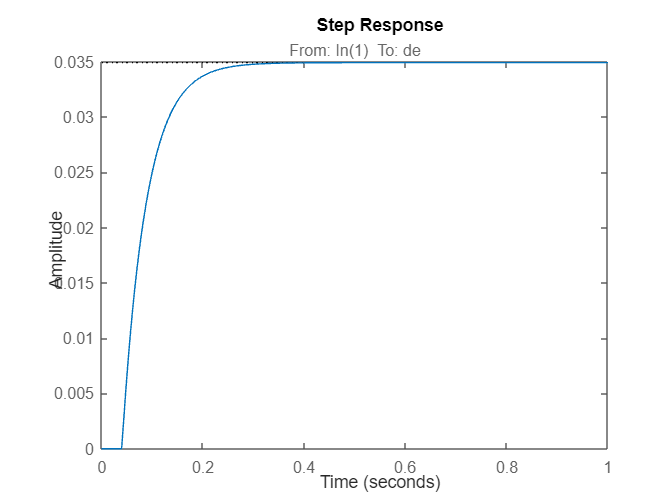

figure, step(Actuators.Act_e('de','cmd_de')*deg2rad(2),1);

damp(Actuators.Act_e)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -2.10e+01     1.00e+00       2.10e+01         4.76e-02    


Note that the damping ratio $\zeta$of the actuation model is 1 as for a first-order system, that is, there is no overshoot. Further note that an input time delay $\tau_e$ is visible in the step response and the steady-state gain of the first-order model is 1 (check by typing '**dcgain(Actuators.Act_e('de','cmd_de'))**' into your command window). This is typical for a servoactuator because an internal controller usually makes sure that the elevator deflects exactly to the commanded value 'cmd_de'. The maximum possible deflection is, of course, constrained by the mechanical design. These limits are provided in the 'Actuators.Limits'-struct in your workspace (the struct is defined in the 'AircraftParameters_Addition_LonMot.m' script). Further, the input delay of the state space model must be implemented in the subsystem. 

**Task 12:** Add an actuator model for the elevator

- open your nonlinear Simulink model 'AircraftModel_LonMot.slx' and get into the 'Actuator (no dyn)' subsystem

- remove the 'gain' block and add a first-order state space model to represent the elevator: implement a 'State Space' block (see the 'Simulink Library')

- parameterize the block appropriately: A: 'Actuators.Act_e.A', etc.

- define the Initial condition: 'TrimPoint.States.debar', give the elevator state a unique name: 'de'

- include the mechanical saturations of the elevator, choose an appropriate block from the 'Simulink Library' and parameterize it

- implement a 'Transport Delay' block (see the 'Simulink Library') in front of the 'State Space' block 

- parameterize the 'Transport Delay' block appropriately to reflect the input time delay of the elevator deflection command and define the initial output to 'TrimPoint.States.debar'

- activate the 'Direct feedthrough' checkbox

- rename the 'Actuator (no dyn)' subsystem to 'Actuator'

- **save your 'AircraftModel_LonMot.slx'** **model**

**Engine Dynamics**

Like the actuation system, the engines of the aircraft are not infinitely fast, i.e., a change in the thrust lever position 'cmd_dt' does not lead to an immediate change in thrust. That is, the thrust force must 'build up over time'. Aircraft engines are highly complex systems. In fact, the complexity of such a system goes beyond the scope of this class. Thus, you will create a so-called 'Hammerstein model' to represent the overall behavior of the propulsion system. A 'Hammerstein model'  consists of a static nonlinear element followed in series by a linear dynamic element. 'Static' here refers to the fact, that the nonlinear function is algebraic, not a differetial equation (it has no state variables). The 'Propulsion System (no dyn)' subsystem in your aircraft model already comprises the static nonlinear element mapping several inputs ($V_A$ , 'Alt' and 'cmd_dt') to the thrust force $X_{P,i}$ (the lookup table within the 'Engine' blocks). The complete dynamics of an aircraft engine are highly complex as well. Instead of modelling it in every detail, you will approximate its dynamics as a first-order system named 'Act_t'. The coefficients of the dynamic system are stored within the 'Propulsion'-struct defined in the 'AircraftParameters_Addition_LonMot.m' script. These linear dynamics are connected in series to the output of the static nonlinear mapping.

**Task 13**: Create a 'Hammerstein' model of the propulsion system

- open the 'AircraftModel_LonMot.slx' model and go into the 'Propulsion System (no dyn)' subsystem

- include a 'Transport Delay' block on the root level of the 'Propulsion System (no dyn)' subsystem **before** the level shift operations

- parameterize the block appropriately to reflect the input time delay of the thrust lever command  'cmd_dt'

- set the initial output to 'TrimPoint.States.dtbar'

- activate the 'Direct feedthrough' checkbox

- modify **both** 'Engine' subsystems by connecting a 'State Space' block to the output 'X_P' of the lookup table each (see the figure below)

        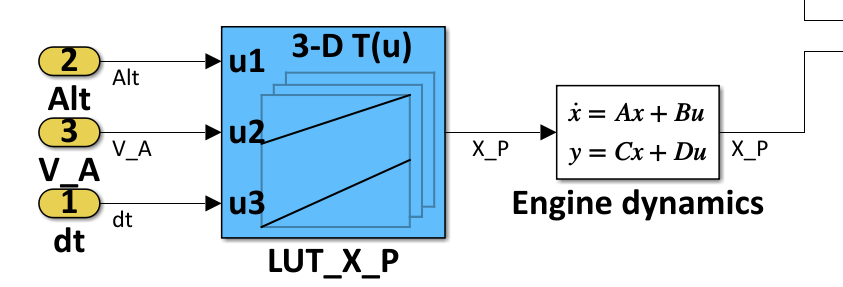

- parameterize the 'State Space' blocks: assume that both engines have the same initial condition 'TrimPoint.States.X_P' but different state names 'X_P1' and 'X_P2'

- rename the 'Propulsion System (no dyn)' subsystem to 'Propulsion System'

- **save your 'AircraftModel_LonMot.slx'** **model**

**Fly in steady state**

With the actuator dynamics and the engine dynamics included into the 'AircraftModel_LonMot.slx' model, the systems' state vector $x$ is now augmented by the elevator state 'de' and the thrust states 'X_P1' and 'X_P2'. Hence, the trim points that you derived in Tasks 2-4 no longer match the Simulink model. In order to initialize the Simulink model in a trim state, you thus need to calculate a new trim point first.

**Task 14: **trim the augmented aircraft model

- open the 'AircraftModel_LonMot.slx' and make sure that it is executable by running **Task 1**

- use the 'Steady State Manager' from Task 2 and create a new 'Trim Specification': rename it to 'TrimState_1_**Aug**Spec'

- can you find differences between the 'TrimState_1_Spec' and the 'TrimState_1_**Aug**Spec'?

- modify the 'TrimState_1_AugSpec': include state and/or input specifications to compute the 'First Trim State' from Task 2

- 'Trim' the aircraft - modify your specification **based on physical insight** in case no solution could be found

- when a solution is found, rename the corresponding 'report' to 'TrimState_1_**Aug**Report'

- create an 'Operating Point' for the obtained trim state: select the 'TrimState_1_**Aug**Report' and 'Extract' the 'Operating Point'

- do **not** use the 'Set Initial Condition' button of the 'Steady State Manager'

- rename the operating point to 'TrimState_1_**Aug**Op'

- export the specification 'TrimState_1_**Aug**Spec', the report 'TrimState_1_**Aug**Report', and the operating point 'TrimState_1_**Aug**Op' to your Matlab workspace

- load the 'MyTrimReports.mat'-file you created in Task 4 (`load 'MyTrimReports'`) and include the new specification, report and operating point of Task 14

- **save the augmented 'MyTrimReports.mat'**

After you've trimmed the augmented nonlinear aircraft model we intend to initialize it in the trim state 'TrimState_1_AugOp'. Given this, the aircraft will maintain its current state and the simulation becomes managable for further use. For example, you can easily investigate the aircrafts' responses to (arbitrary) input changes or its behaviour in the presence of wind. Given this, you can and will start to implement control laws into the simulation model in Part II of the TermProject.

**Task 15:** initialize your Simulink aircraft model in a trim state

- open the 'AircraftParameters_LonMot.m' script

- modify the entries within the 'Trim Point' section (see below) to match the trim states of 'TrimState_1_AugOp': type in the values by hand **as precisely as possible** (erase any calculations such as `deg2rad `, etc.)

- **save the changes you've made within the 'AircraftParameters_LonMot.m' script**

- **The figure below is just an example. Use your own trim values in case they differ from the ones shown below.**

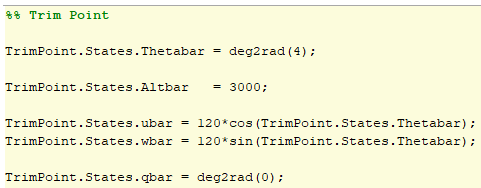

- remove the inports 'cmd_de' and cmd_dt' within the root level of the  'AircraftModel_LonMot.slx' model: replace them by 'Constant' blocks of the same name

          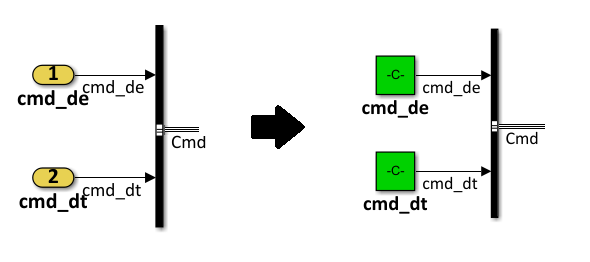

- specify the constant output values to 'TrimPoint.States.debar' and 'TrimPoint.States.dtbar', respectively

- add a 'To Workspace' block (see Simulink Library) to the root level of the aircraft model: connect it to the 'EoM'- signal bus

 

- specify the 'Variable name' and the 'Decimation' parameters of the 'To Workspace' block to 'trim_check' and '2', respectively

- run the subsequent check section to ensure that the aircraft finally is in a trim state (note the scale of the y-axis)

- **save the 'AircraftModel_LonMot.slx' model**

**Check: ** Run this section to check whether your trim point of the augmented model is stable over the simulation time. 

**Warning! **This code section clears your Matlab workspace! Save variables of interest to you before running this section

clear, clc

addpath('1_Model_LongitudinalMotion')
addpath('1_Model_LongitudinalMotion\1_Checks\')
addpath('2_Model_TrimLinearize')

run("AircraftParameters_LonMot.m");
run ("AircraftParameters_Addition_LonMot.m"); 

[out] = sim('AircraftModel_LonMot.slx');  % run simulation to check if the aircraft model remains in steady state

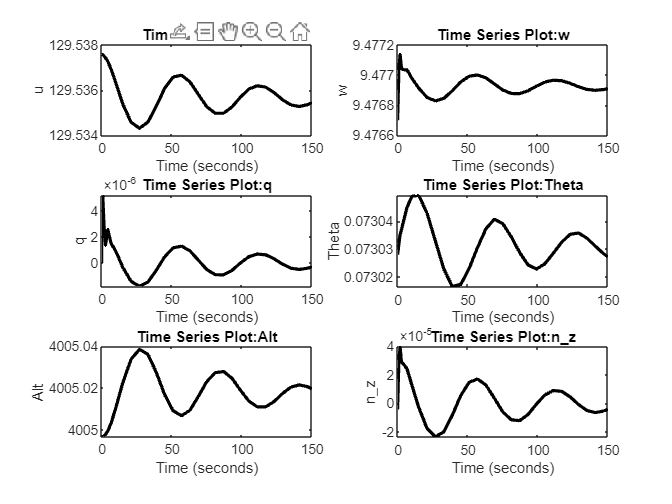

figure(240); clf
    subplot(3,2,1), plot(out.trim_check.vv_f.u,'k','linewidth',2), ...
    subplot(3,2,2), plot(out.trim_check.vv_f.w,'k','linewidth',2), ...
    subplot(3,2,3), plot(out.trim_check.q,'k','linewidth',2), ...
    subplot(3,2,4), plot(out.trim_check.Theta,'k','linewidth',2), ...
    subplot(3,2,5), plot(out.trim_check.Alt,'k','linewidth',2), ...
    subplot(3,2,6), plot(out.trim_check.nn_f.n_z,'k','linewidth',2), ...
clear out

% end of file